# PALA_InVivoULM_example.m : Post Processing - filtering, localization and tracking for in vivo data

Simple script to perform ULM on in vivo data IQ are loaded, filtered and sent into ULM processing. Bubbles are detected, selected, then localized, and paired into tracks. The result is a list of interpolated tracks to reconstructed a full brain vascularization.

This code can be easily adapted for any other in vivo datasets.

Created by Arthur Chavignon 25/02/2020

DATE 2020.12.17 - VERSION 1.1 AUTHORS: Arthur Chavignon, Baptiste Heiles, Vincent Hingot. CNRS, Sorbonne Universite, INSERM. Laboratoire d'Imagerie Biomedicale, Team PPM. 15 rue de l'Ecole de Medecine, 75006, Paris Code Available under Creative Commons Attribution-NonCommercial-ShareAlike 4.0 International (see [https://creativecommons.org/licenses/by-nc-sa/4.0/](https://creativecommons.org/licenses/by-nc-sa/4.0/)) ACADEMIC REFERENCES TO BE CITED Details of the code in the article by Heiles, Chavignon, Hingot, Lopez, Teston and Couture. Performance benchmarking of microbubble-localization algorithms for ultrasound localization microscopy, Nature Biomedical Engineering, 2021. General description of super-resolution in: Couture et al., Ultrasound localization microscopy and super-resolution: A state of the art, IEEE UFFC 2018

run('PALA_SetUpPaths.m')

## Selected data file and saving folders

workingdir = [PALA_data_folder];
filename = 'PALA_InVivoRatBrain_';
cd(workingdir)

mydatapath = [workingdir 'IQ\'];
workingdir = [workingdir '\Example'];mkdir(workingdir)


IQfiles = dir([mydatapath '*.mat']);
% [IQfiles(1).folder filesep IQfiles(1).name]
load([IQfiles(1).folder filesep IQfiles(1).name],'UF','PData');

## Adapt parameters to your data

A few parameters must be provided by the user depending of your input images (size of pixel, wavelength) These parameters will be copied and used later during the creation of the ULM structure.

load([IQfiles(1).folder filesep IQfiles(1).name],'IQ','UF');
% in this example, UF.TwFreq = 15MHz, UF.FrameRateUF = 1000Hz;

% Here you put the size of your data
SizeOfBloc = size(IQ);              % [nb_pixel_z,nb_pixel_x, nb_frame_per_bloc]

% Here you put the size of pixel in the prefered unit. It can be um, mm, m, wavelength, or an arbitrary scale.
ScaleOfPixel = [1 1];               % [pixel_size_z, pixel_size_x]
% In that example, the size of pixels is lambda x lambda. The localization process will be
% performs in wavelength. For velocity rendering, velocities in [wavelength/s] will be converted in [mm/s].

% The imaging frame rate is required for velocity calculation, and temporal filtering.
framerate = UF.FrameRateUF;          % imaging framerate in [Hz]

% Number of blocs to process
Nbuffers = numel(IQfiles);          % number of bloc to process (used in the parfor)

% If pixel sizes are in wavelength, lambda must be provided for a velocity maps in mm/s,
lambda = 1540/(UF.TwFreq*1e3);      % in metrics like mm, um, cm... it will define the unity of the velocity (speed of sound/ frequency)
clear P UF IQ

## ULM parameters

this script can be run using different scaling, it can be wavelength, pixel size, mm, um. In this example, input pixel are isotropic and equal to lambda (pixelPitch_x = pixelPitch_y = lambda) All size defined later are expressed in lambda

res = 10; % final ratio of localization rendering, it's approximately resolution factor of localization in scale(1) units.
% for a pixel size of 100um, we can assume that ULM algorithm provides precision 10 (res) times
% smaller than pixel size. Final rendering will be reconstructed on a 10x10um grid.

ULM = struct('numberOfParticles', 70,...  % Number of particles per frame. (30-100)
    'size',[SizeOfBloc(1) SizeOfBloc(2) SizeOfBloc(3)],... % size of input data [nb_pixel_z nb_pixel_x nb_frame_per_bloc]
    'scale',[ScaleOfPixel 1/framerate],...% Scale [z x dt], size of pixel in the scaling unit. (here, pixsize = 1*lambda)
    'res',res,...                       % Resolution factor. Typically 10 for final image rendering at lambda/10.
    'SVD_cutoff',[5 SizeOfBloc(3)],...  % SVD filtering, to be adapted to your clutter/SNR levels
    'max_linking_distance',2,...        % Maximum linking distance between two frames to reject pairing, in pixels units (UF.scale(1)). (2-4 pixel).
    'min_length', 15,...                % Minimum allowed length of the tracks in time. (5-20 frames)
    'fwhm',[1 1]*3,...                  % Size [pixel] of the mask for localization. (3x3 for pixel at lambda, 5x5 at lambda/2). [fmwhz fmwhx]
    'max_gap_closing', 0,...            % Allowed gap in microbubbles' pairing. (if you want to skip frames 0)
    'interp_factor',1/res,...           % Interpfactor (decimation of tracks)
    'LocMethod','Radial'...             % Select localization algorithm (WA,Interp,Radial,CurveFitting,NoLocalization)
    );
ULM.ButterCuttofFreq = [50 249];        % Cutoff frequency (Hz) for additional filter. Typically [20 300] at 1kHz.
ULM.parameters.NLocalMax = 3;           % Safeguard on the number of maxLocal in the fwhm*fwhm grid (3 for fwhm=3, 7 for fwhm=5)
[but_b,but_a] = butter(2,ULM.ButterCuttofFreq/(framerate/2),'bandpass');
ULM.lambda = lambda;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Load data and localize microbubbles %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear IQ Track_tot Track_tot_interp ProcessingTime
tic;Track_tot = {};
fprintf('--- ULM PROCESSING --- \n\n');t1=tic;

--- ULM PROCESSING --- 



parfor hhh = Nbuffers:min(999,Nbuffers) % can be used with parallel pool
% for hhh = 1:min(999,Nbuffers) % can be used with parallel pool
% for hhh = 1:Nbuffers
    fprintf('Processing bloc %d/%d\n',hhh,Nbuffers);
    % Load IQ data (or other kind of images without compression)
    tmp = load([IQfiles(hhh).folder filesep IQfiles(hhh).name],'IQ');

    % Filtering of IQ to remove clutter (optional)
    IQ_filt = SVDfilter(tmp.IQ,ULM.SVD_cutoff);tmp = [];

    % Temporal filtering
    IQ_filt = filter(but_b,but_a,IQ_filt,[],3); %(optional)
    IQ_filt(~isfinite(IQ_filt))=0;

    % Detection and localization process (return a list of coordinates in pixel)
    [MatTracking] = ULM_localization2D(abs(IQ_filt),ULM); IQ_filt=[];

    % Convert pixel into isogrid (pixel are not necessary isometric);
    MatTracking(:,2:3) = (MatTracking(:,2:3) - [1 1]).*ULM.scale(1:2);

    % Tracking algorithm (list of tracks)
    Track_tot_i = ULM_tracking2D(MatTracking,ULM);

    % Saving part:
    %--- if for, you can save tracks at each loop to avoid RAM out of memory
    % save([workingdir filesep filename '_tracks' num2str(hhh,'%.3d') '.mat'],'Track_tot_i','ULM') %
    %--- if parfor you can cat all tracks in a huge cells variable
    Track_tot{hhh} = Track_tot_i;
    Track_tot_i={};MatTracking = [];
end

Processing bloc 4/4


Track_tot = cat(1,Track_tot{:});
Tend = toc(t1);disp('Done')

Done


fprintf('ULM done in %d hours %.1f minutes.\n', floor(Tend/60/60), rem(Tend/60,60));

ULM done in 0 hours 0.1 minutes.


## Create individual variable to save using v6 version.

By cutting Tracks into different variables small than 2GB, the save v6 is faster than save v7.3

CutTracks = round(linspace(1,numel(Track_tot),4));
Track_tot_1 = Track_tot(CutTracks(1):CutTracks(2)-1);
Track_tot_2 = Track_tot(CutTracks(2):CutTracks(3)-1);
Track_tot_3 = Track_tot(CutTracks(3):end);
save([workingdir filesep filename 'example_tracks.mat'],'Track_tot_1','Track_tot_2','Track_tot_3','Tend','ULM','-v6')
clear Track_tot_1 Track_tot_2 Track_tot_3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Create MatOut %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

create the MatOut density with interpolated tracks for visual analysis, and with non interpolated tracks for aliasing index calculation. Define the size of SRpixel for displaying (default 10)

ULM.SRscale = ULM.scale(1)/ULM.res;
ULM.SRsize = round(ULM.size(1:2).*ULM.scale(1:2)/ULM.SRscale);

% Convert tracks into SRpixel
Track_matout = cellfun(@(x) (x(:,[1 2 3 4])+[1 1 0 0]*1)./[ULM.SRscale ULM.SRscale 1 1],Track_tot,'UniformOutput',0);
llz = [0:ULM.SRsize(1)]*ULM.SRscale;llx = [0:ULM.SRsize(2)]*ULM.SRscale;

## Accumulate tracks on the final MatOut grid.

fprintf('--- CREATING MATOUTS --- \n\n')

--- CREATING MATOUTS --- 



MatOut = ULM_Track2MatOut(Track_matout,ULM.SRsize+[1 1]*1); %pos in superpix [z x]

Building 2D ULM image (size : 781  1181).


## MatOut intensity rendering, with compression factor

fprintf('--- GENERATING IMAGE RENDERINGS --- \n\n')

--- GENERATING IMAGE RENDERINGS --- 



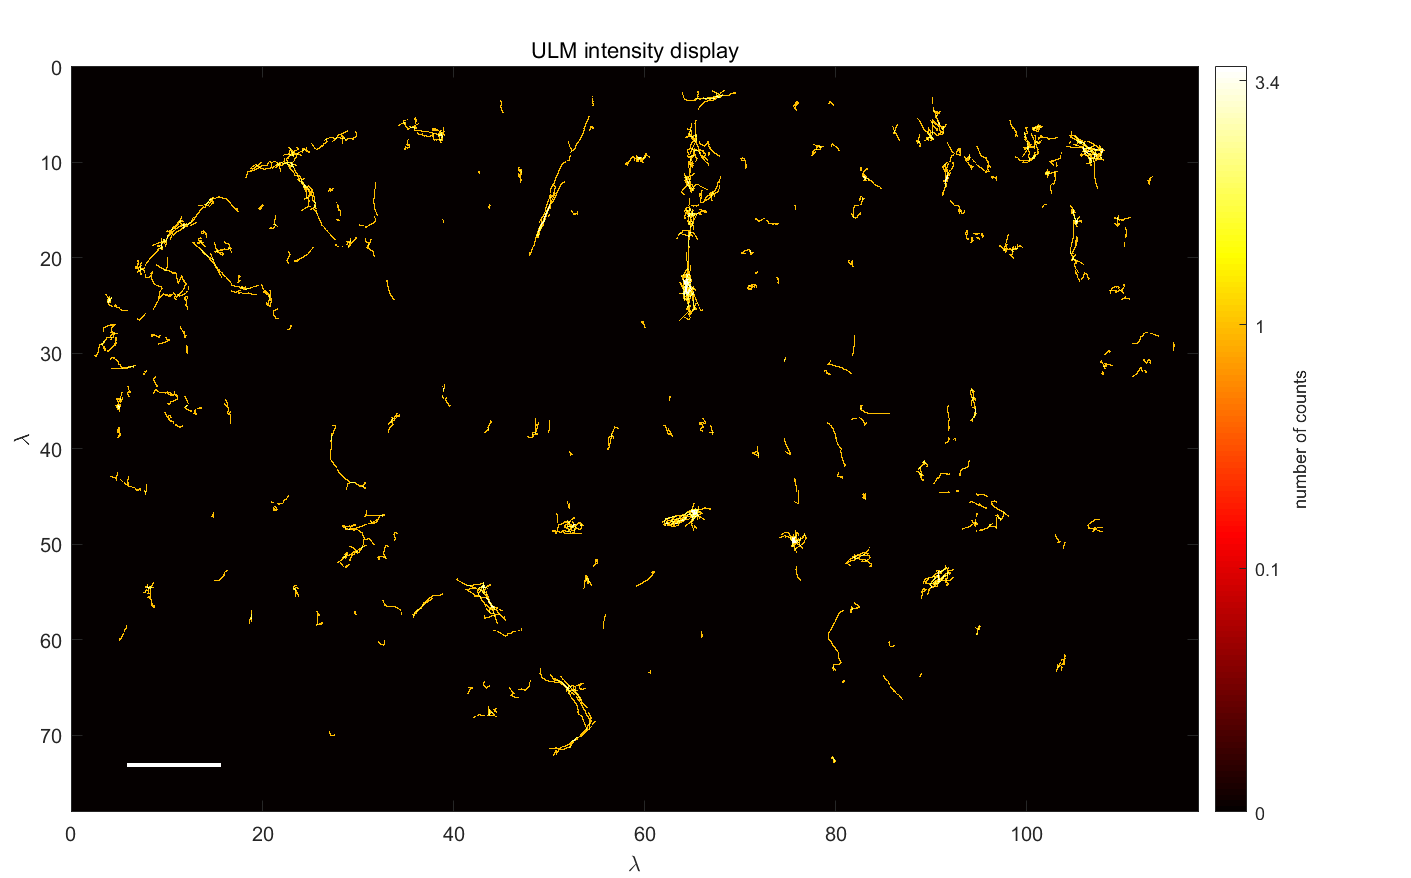

figure(1);clf,set(gcf,'Position',[652 393 941 585]);
IntPower = 1/3;SigmaGauss=0;
im=imagesc(llx,llz,MatOut.^IntPower);axis image
if SigmaGauss>0,im.CData = imgaussfilt(im.CData,SigmaGauss);end

title('ULM intensity display')
% colormap(gca,gray(128))
colormap(gca,hot(128))
clbar = colorbar;caxis(caxis*.8)  % add saturation in image
clbar.Label.String = 'number of counts';
clbar.TickLabels = round(clbar.Ticks.^(1/IntPower),1);xlabel('\lambda');ylabel('\lambda')
ca = gca;ca.Position = [.05 .05 .8 .9];
BarWidth = round(1./(ULM.SRscale*lambda)); % 1 mm
im.CData(size(MatOut,1)-50+[0:3],60+[0:BarWidth])=max(caxis);

print(gcf,[workingdir filesep filename 'example_MatOut'],'-dpng','-r750')

WriteTif(im.CData,ca.Colormap,[workingdir filesep filename 'example_MatOut.tif'],'caxis',caxis,'Overwrite',1)